## Initialize Parameters for sim

FFT_LENGTH = 512;
specAvg = 27;

## Filter valid data

% k = find(out.SciInfo_Valid.Data, 1);
% fftData = out.SciInfo.Data(k:end);
k = find(out.mag_valid, 1)

k = 1118

fftData = out.mag_out(k:end);
fftData = reshape(fftData, [], 1); % Ensure fftData is 2D for plotting later

## Arrange data in columns with 512 (FFT_LENGTH) Rows

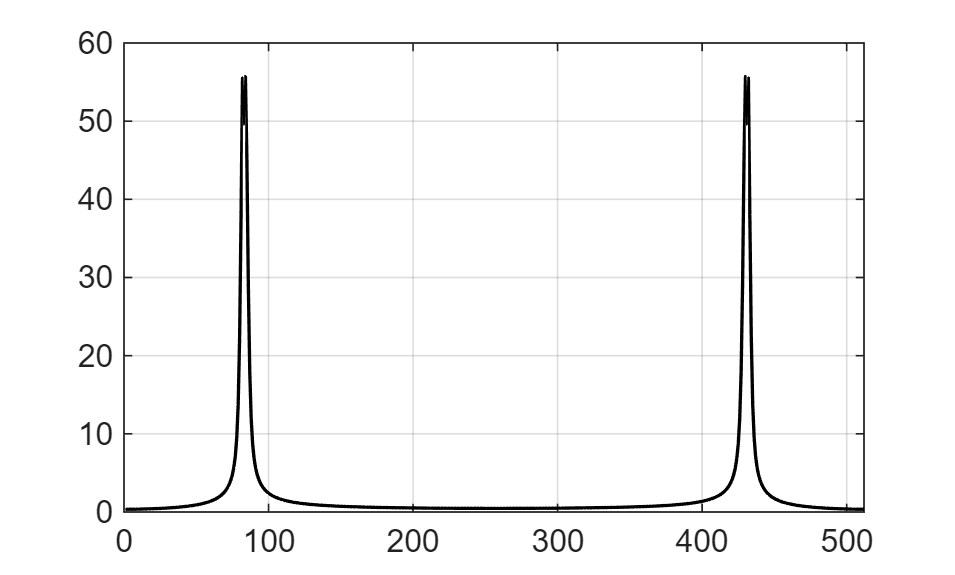

a = 1:FFT_LENGTH;
a = a';
% subplot(2, 1, 1)
figure;
plot(a, fftData(1:FFT_LENGTH), 'k', 'LineWidth', 1)
xlim([0 FFT_LENGTH])
grid on;

## Find number of spectral averages

% specAvg = ceil(length(fftData)/FFT_LENGTH/2)
specAvg = floor(length(fftData)/FFT_LENGTH) - 1

specAvg = 26

% specAvg = 30
fftData_snr1 = fftData(1:specAvg*FFT_LENGTH);
fftData_snr2 = reshape(fftData_snr1, FFT_LENGTH, specAvg);

## Sum along columns and plot

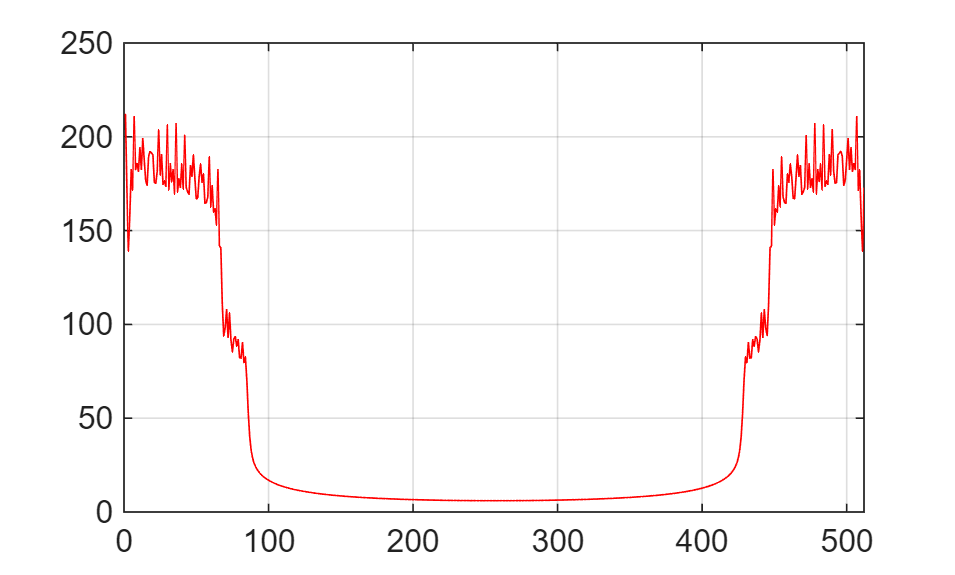

fftData_snr3 = sum(fftData_snr2, 2);

% subplot(2, 1, 2)
figure;
plot(a, fftData_snr3, 'r')
xlim([0 FFT_LENGTH])
grid on;

## Plot data over frequency

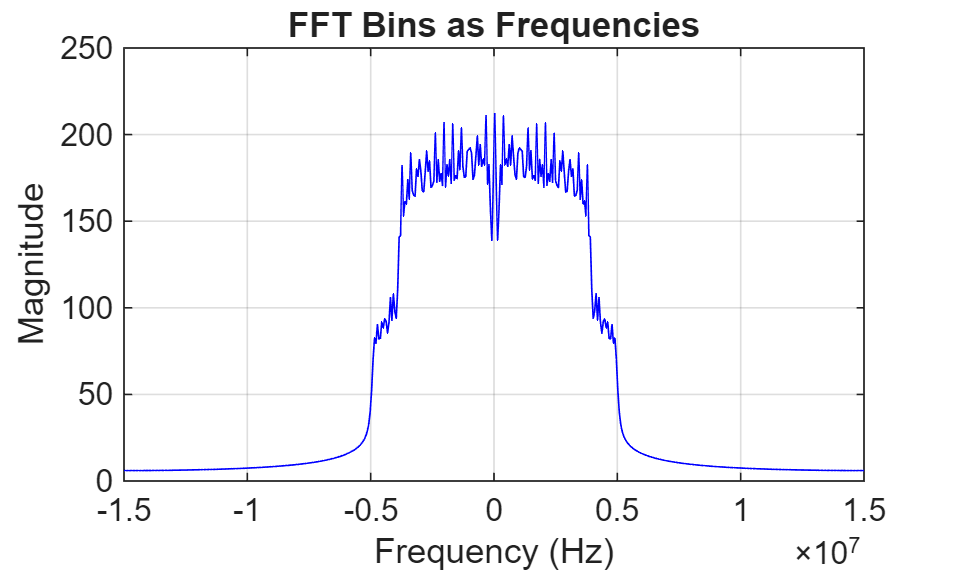

frequencies = linspace(-Fs/4, Fs/4, FFT_LENGTH); % /4 because this is downsampled
figure;
plot(frequencies, fftshift(fftData_snr3), 'b')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('FFT Bins as Frequencies')
xlim([-Fs/4 Fs/4])
grid on;

## Plot Simulink Results

% % Plot the Simulink results from out.SpecAvg and out.SpecAvg_Valid
validIndices = find(out.avg_valid, 1)

validIndices = 14430

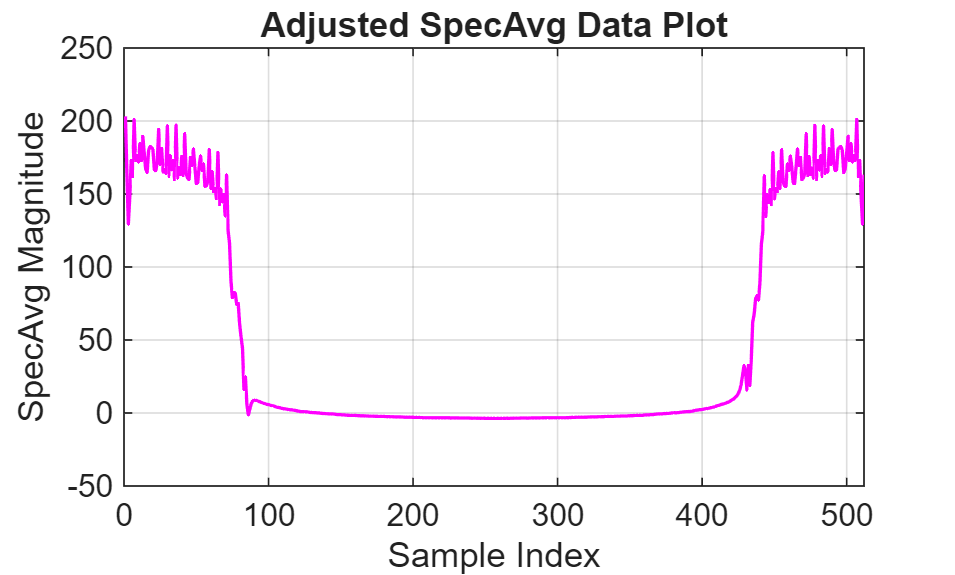

specAvgData = out.avg_out(validIndices:end);
specAvgData = reshape(specAvgData, [], 1); % Ensure specAvgData is 2D for plotting later

% Ensure specAvgData is of appropriate size for plotting
% Allows plotting partial FFTs if specAvg is too large
if length(specAvgData) < FFT_LENGTH
    specAvgData = [specAvgData; zeros(FFT_LENGTH - length(specAvgData), 1)]; % Pad with zeros if necessary
else
    specAvgData = specAvgData(1:FFT_LENGTH); % Truncate if too long
end

figure;
plot(a, specAvgData, 'm', 'LineWidth', 1)
xlim([0 FFT_LENGTH])
grid on;
xlabel('Sample Index')
ylabel('SpecAvg Magnitude')
title('Adjusted SpecAvg Data Plot')

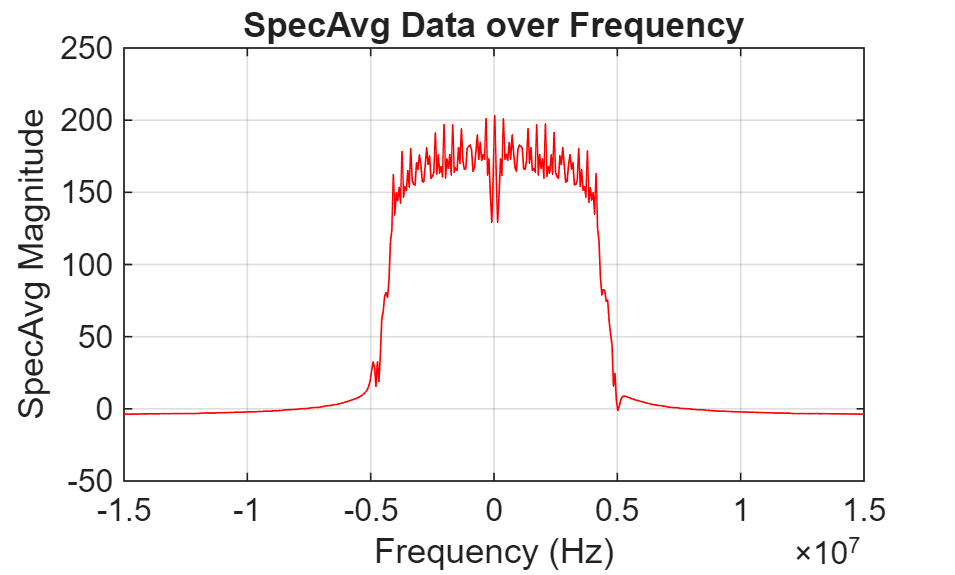


% Plot the Simulink results over the frequency axis
figure;
plot(frequencies, fftshift(specAvgData), 'r')
xlabel('Frequency (Hz)')
ylabel('SpecAvg Magnitude')
title('SpecAvg Data over Frequency')
xlim([-Fs/4 Fs/4])
grid on;